clc
clear all
x=[];
y=[];
%Get image from camera feed
load("C.mat");
Ix = C=="Road";
Ix=imresize(Ix,[144 176]);

%Ix = imread('k1.png');  % read the image into the matrix
imshow(Ix);                % display the image 
[x,y] = getpts;

Error using getpts (line 174)
Interruption during mouse point selection.

x1=x(1);y1=y(1);
x2=x(2);y2=y(2);
x3=x(3);y3=y(3);
x4=x(4);y4=y(4);

s=[];
t=[];
%Vitrual top-down view image
I = imread(['k2.png']);  % read the image into the matrix
imshow(I);                % display the image 
[s,t] = getpts;
u1=s(1);v1=t(1);
u2=s(2);v2=t(2);
u3=s(3);v3=t(3);
u4=s(4);v4=t(4);


A=[x1 y1 1 0 0 0 -u1*x1 -u1*y1 -u1;
    0 0 0 x1 y1 1 -v1*x1 -v1*y1 -v1;
    x2 y2 1 0 0 0 -u2*x2 -u2*y2 -u2;
    0 0 0 x2 y2 1 -v2*x2 -v2*y2 -v2;
    x3 y3 1 0 0 0 -u3*x3 -u3*y3 -u3;
    0 0 0 x3 y3 1 -v3*x3 -v3*y3 -v3;
    x4 y4 1 0 0 0 -u4*x4 -u4*y4 -u4;
    0 0 0 x4 y4 1 -v4*x4 -v4*y4 -v4]; 
Atrans=A';
[V,D]=eig(Atrans*A);


C=mod(find(D==min(D(D>0))),9)
H=[V(1,C) V(2,C) V(3,C);
    V(4,C) V(5,C) V(6,C);
    V(7,C) V(8,C) V(9,C)];

X=[x2 y2 1]
U_=[u2 v2 1]
%alpha=1/(H(3,1)*X(1)+H(3,2)*X(2)+H(3,3));
%H=alpha*H;
U=H*X'
U/U(3)

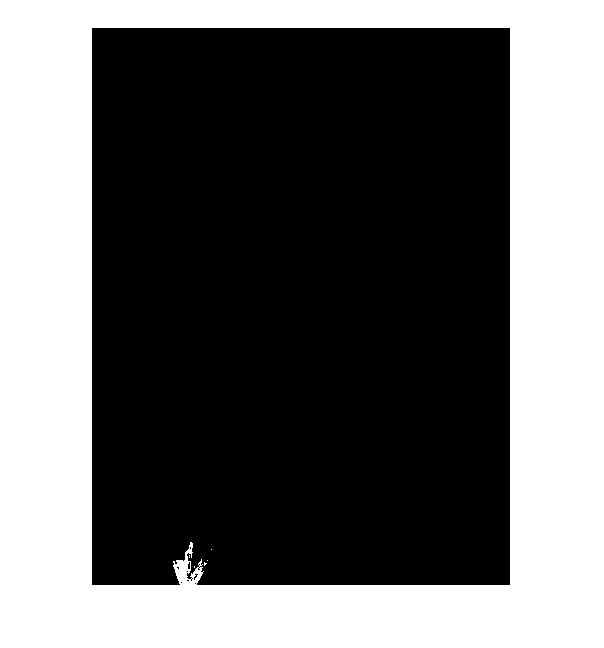

%load('Homography.mat')
T = projective2d(H');
J = imwarp(Ix,T);
imshow(J);